Ennek az MLX-nek a célja, hogy egy rövid, hatékony másolható kódot tároljon Boda diagram készítéséhez és előzetes kiszámolásához RC áramkör esetén.

## Logaritmikusan lineáris eloszlás

% egy tömböt ad vissza totalCount hosszal, az egyes mérési frekvenciákat
loglin = @(totalCount, f_floor, f_ceiling) ...
    f_floor .* (f_ceiling/f_floor) .^ ((0:(totalCount -1)) / (totalCount - 1));

## Integráló RC áramkör 

C = 22 * 10 ^ (-9);
R = 10000;

Tau = R * C;
omega_cutoff = 1 / Tau;
f_cutoff = omega_cutoff / (2 * pi); % Pólus frekvencia 

f_floor = f_cutoff * 10^(-1);
f_ceiling = f_cutoff * 10;
measure_count = 21;
f_measure = loglin(measure_count, f_floor, f_ceiling);

U_ki_int = @(u_be, f) u_be .* (1 ./ (1 + 1i * ((f * 2 * pi) / omega_cutoff)));

effectation_int = @(f) U_ki_int(1, f) ./ 1;

phase_diff_int = @(f) atan2d(imag(effectation_int(f)), real(effectation_int(f)));
dampening_int = @(f) abs(effectation_int(f));
dampening_db_int = @(f) 20 * log10(dampening_int(f));

a_db_f = dampening_db_int(f_measure);
fi_f = phase_diff_int(f_measure);

% Valós mérések
a_db_f_measured = [-0 -0.1 -0.1 -0.2 -0.3 -0.5 -0.7 -1 -1.5 -2.2 ...
    -3.1 -4 -5.4 -6.8 -8.6 -10.1 -11.8 -13.9 -15 -17.4 -19.9] 

a_db_f_measured =          0   -0.1000   -0.1000   -0.2000   -0.3000   -0.5000   -0.7000   -1.0000   -1.5000   -2.2000   -3.1000   -4.0000   -5.4000   -6.8000   -8.6000  -10.1000  -11.8000  -13.9000  -15.0000  -17.4000  -19.9000


fi_f_deg_measured = [-5.7 -7.1 -9 -11.2 -14.2 -17.5 -21.2 -26.2 -31.9 -37.8 ...
    -44.2 -50.1 -56.3 -61.9 -67.1 -70.8 -74.1 -77.3 -78.8 -81.2 -83.1] 

fi_f_deg_measured =    -5.7000   -7.1000   -9.0000  -11.2000  -14.2000  -17.5000  -21.2000  -26.2000  -31.9000  -37.8000  -44.2000  -50.1000  -56.3000  -61.9000  -67.1000  -70.8000  -74.1000  -77.3000  -78.8000  -81.2000  -83.1000



% Megjelenítés
calced_val = table(f_measure', a_db_f', fi_f', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);

measured_val = table(f_measure', a_db_f_measured', fi_f_deg_measured', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);

disp("Számított értékek táblázatban");

Számított értékek táblázatban


display(calced_val);

calced_val = 21×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

            72.343             -0.043214      -5.7106 
            91.075             -0.068291      -7.1754 
            114.66              -0.10774      -9.0059 
            144.34              -0.16954      -11.284 
            181.72              -0.26572        -14.1 
            228.77              -0.41393      -17.548 
               288              -0.63892      -21.708 
            362.57              -0.97323      -26.619 
            456.45               -1.4554       -32.25 
            574.64               -2.1244      -38.461 
            723.43               -3.0103          -45 
            910.75               -4.1244      -51.539 
            1146.6               -5.4554       -57.75 
            1443.4               -6.9732      -6

disp("Mért értékek táblázatban");

Mért értékek táblázatban


display(measured_val);

measured_val = 21×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

            72.343                   0          -5.7  
            91.075                -0.1          -7.1  
            114.66                -0.1            -9  
            144.34                -0.2         -11.2  
            181.72                -0.3         -14.2  
            228.77                -0.5         -17.5  
               288                -0.7         -21.2  
            362.57                  -1         -26.2  
            456.45                -1.5         -31.9  
            574.64                -2.2         -37.8  
            723.43                -3.1         -44.2  
            910.75                  -4         -50.1  
            1146.6                -5.4         -56.3  
            1443.4                -6.8        

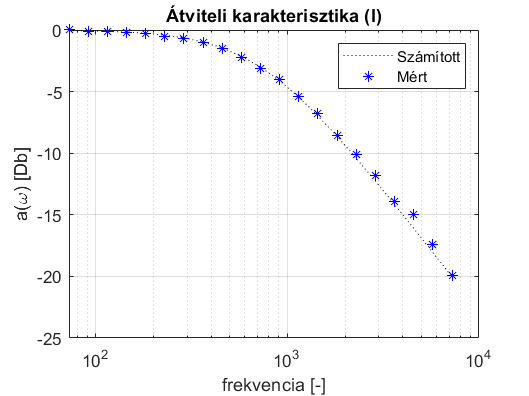


figure();
semilogx(f_measure, a_db_f, "k:"); hold on; grid on;
semilogx(f_measure, a_db_f_measured, "b*");
xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");
legend(["Számított", "Mért"])

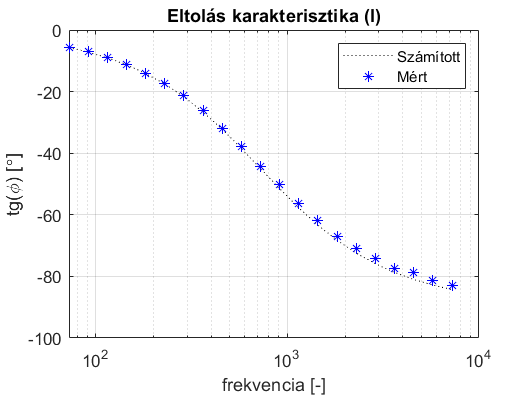


figure();
semilogx(f_measure, fi_f, "k:"); hold on; grid on;
semilogx(f_measure, fi_f_deg_measured, "b*"); 
xlabel("frekvencia [-]");
ylabel("tg(\phi) [\circ]");
title("Eltolás karakterisztika (I)");
legend(["Számított", "Mért"])

## Deriváló RC áramkör

C = 22 * 10 ^ (-9);
R = 10000;

Tau = R * C;
omega_cutoff = 1 / Tau;
f_cutoff = omega_cutoff / (2 * pi); % Pólus frekvencia 

U_ki_der = @(u_be, f) u_be .* (1i .* ((f * 2 * pi) / omega_cutoff) ...
    ./ (1 + 1i * ((f * 2 * pi) / omega_cutoff)));

effectation_der = @(f) U_ki_der(1, f) ./ 1;

phase_diff_der = @(f) atan2d(imag(effectation_der(f)), real(effectation_int(f)));
dampening_der = @(f) abs(effectation_der(f));
dampening_db_der = @(f) 20 * log10(dampening_der(f));

a_db_f = dampening_db_der(f_measure);
fi_f = phase_diff_der(f_measure);

% Valós mérések
a_db_f_measured = [-19.8 -17.9 -16.3 -14.1 -12.3 -10.4 -8.8 -7.1 -5.6 -4.3 ...
    -3.2 -2.3 -1.6 -1.1 -0.8 -0.5 -0.4 -0.2 -0.2 -0.1 -0.1] 

a_db_f_measured =   -19.8000  -17.9000  -16.3000  -14.1000  -12.3000  -10.4000   -8.8000   -7.1000   -5.6000   -4.3000   -3.2000   -2.3000   -1.6000   -1.1000   -0.8000   -0.5000   -0.4000   -0.2000   -0.2000   -0.1000   -0.1000


fi_f_deg_measured = [-82.6 -81.2 -79.6 -77.1 -74.4 -71 -67 -62.4 -56.9 -50.7 ...
    -44.8 -38.3 -32.5 -27.1 -22.3 -18.6 -14.7 -11.6 -9.5 -7.8 -6.1] 

fi_f_deg_measured =   -82.6000  -81.2000  -79.6000  -77.1000  -74.4000  -71.0000  -67.0000  -62.4000  -56.9000  -50.7000  -44.8000  -38.3000  -32.5000  -27.1000  -22.3000  -18.6000  -14.7000  -11.6000   -9.5000   -7.8000   -6.1000



% Megjelenítés
calced_val = table(f_measure', a_db_f', fi_f', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);

measured_val = table(f_measure', a_db_f_measured', fi_f_deg_measured', ...
    'VariableNames', ["Mérési frenvencia (Hz)", "Átvitel (dB)", "Szög (°)"]);

disp("Számított értékek táblázatban");

Számított értékek táblázatban


display(calced_val);

calced_val = 21×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

            72.343               -20.043       5.7106 
            91.075               -18.068       7.1754 
            114.66               -16.108       9.0059 
            144.34                -14.17       11.284 
            181.72               -12.266         14.1 
            228.77               -10.414       17.548 
               288               -8.6389       21.708 
            362.57               -6.9732       26.619 
            456.45               -5.4554        32.25 
            574.64               -4.1244       38.461 
            723.43               -3.0103           45 
            910.75               -2.1244       51.539 
            1146.6               -1.4554        57.75 
            1443.4              -0.97323       6

disp("Mért értékek táblázatban");

Mért értékek táblázatban


display(measured_val);

measured_val = 21×3 table
    Mérési frenvencia (Hz)    Átvitel (dB)    Szög (°)
    ______________________    ____________    ________

            72.343               -19.8         -82.6  
            91.075               -17.9         -81.2  
            114.66               -16.3         -79.6  
            144.34               -14.1         -77.1  
            181.72               -12.3         -74.4  
            228.77               -10.4           -71  
               288                -8.8           -67  
            362.57                -7.1         -62.4  
            456.45                -5.6         -56.9  
            574.64                -4.3         -50.7  
            723.43                -3.2         -44.8  
            910.75                -2.3         -38.3  
            1146.6                -1.6         -32.5  
            1443.4                -1.1        

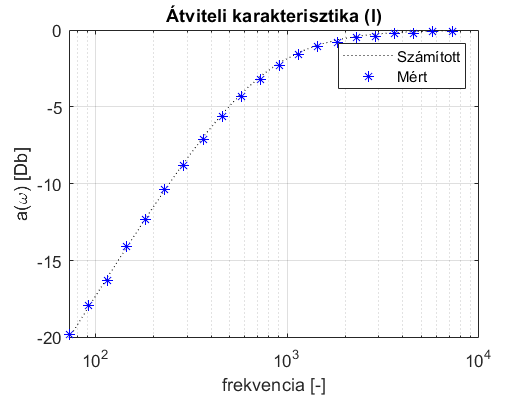


figure();
semilogx(f_measure, a_db_f, "k:"); hold on; grid on;
semilogx(f_measure, a_db_f_measured, "b*");
xlabel("frekvencia [-]");
ylabel("a(\omega) [Db]");
title("Átviteli karakterisztika (I)");
legend(["Számított", "Mért"])

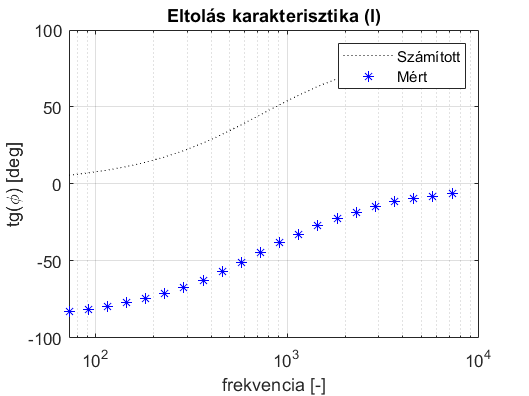


figure();
semilogx(f_measure, fi_f, "k:"); hold on; grid on;
semilogx(f_measure, fi_f_deg_measured, "b*"); 
xlabel("frekvencia [-]");
ylabel("tg(\phi) [deg]");
title("Eltolás karakterisztika (I)");
legend(["Számított", "Mért"])